# Sorption Tailfingen

load('tailfingen_sorption.txt')

Cw = tailfingen_sorption(:,1);
Cs = tailfingen_sorption(:,2);
b  = [1,0.5]; % b(1) = K, b(2) = n

[beta,R,J,CovB,MSE] = nlinfit(Cw,Cs,@(b,x)(b(1).*x.^b(2)),b);
Kt  = beta(1)

Kt = 2.2972

nt  = beta(2)

nt = 0.8922

SEt = sqrt(diag(CovB))

SEt =     2.1920
    0.1339


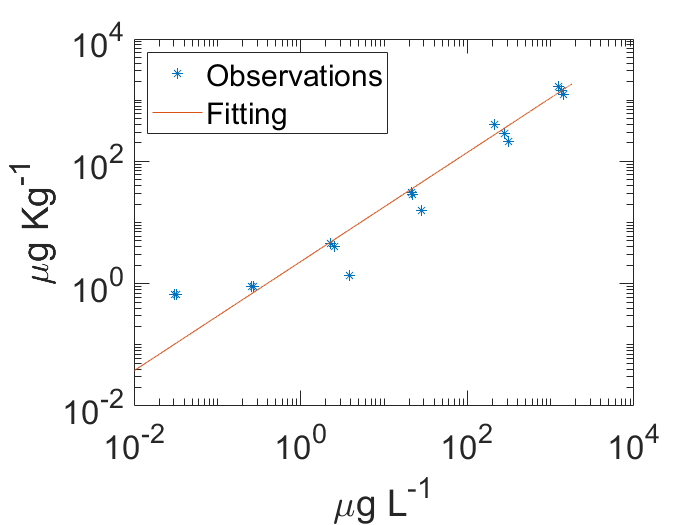

xt  = linspace(1e-2,1800,1800);
yt  = beta(1).*xt.^beta(2); 

figure(1)
A = plot(Cw,Cs,'*');
hold on
B = plot(xt,yt);
set(gca,'FontSize',20,'TickLength',[0.030 0.015],'YScale','log','XScale','log')
legend([A B],'Observations','Fitting','Location','northwest')
xlabel('\mug L^{-1}')
ylabel('\mug Kg^{-1}')
hold off

## Sorption Poltringen

load('poltringen_sorption.txt')

Two observations are missing, so I am doing the fitting with 16 points instead of 18.


Cw = vertcat(poltringen_sorption(1:14,1),poltringen_sorption(17:18,1));
Cs = vertcat(poltringen_sorption(1:14,2),poltringen_sorption(17:18,1));
b  = [1,0.5]; % b(1) = K, b(2) = n

[beta1,R1,J1,CovB1,MSE1] = nlinfit(Cw,Cs,@(b,x)(b(1).*x.^b(2)),b);
SE1 = sqrt(diag(CovB1));
Kp  = beta1(1)

Kp = 4.1605

np  = beta1(2)

np = 0.8051

SEp = sqrt(diag(CovB1))

SEp =     0.6768
    0.0226


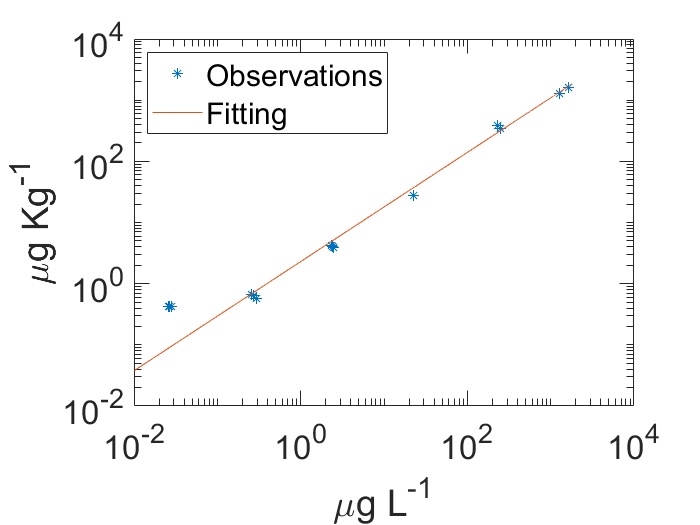

xp  = linspace(1e-2,1800,1800);
yp  = beta(1).*xp.^beta(2); 

figure(2)
A = plot(Cw,Cs,'*');
hold on
B = plot(xp,yp);
set(gca,'FontSize',20,'TickLength',[0.030 0.015],'YScale','log','XScale','log')
legend([A B],'Observations','Fitting','Location','northwest')
xlabel('\mug L^{-1}')
ylabel('\mug Kg^{-1}')
hold off